opts = delimitedTextImportOptions("NumVariables", 7);

% Specify range and delimiter
opts.DataLines = [1, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["Type", "Time", "Message", "VarName4", "VarName5", "VarName6", "VarName7"];
opts.VariableTypes = ["categorical", "double", "string", "double", "double", "double", "string"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Specify variable properties
opts = setvaropts(opts, "VarName7", "WhitespaceRule", "preserve");
opts = setvaropts(opts, ["Type", "Message", "VarName7"], "EmptyFieldRule", "auto");

% Import the data
systemlog = readtable("system_log.txt", opts);


%% Clear temporary variables
clear opts
% 
systemlog = systemlog(~(systemlog.Message == "Can tx buffer full"),:);
systemlog = systemlog(systemlog.Type == "[MESSAGE]",:);
coeff_idx = find(contains(systemlog.Message,"coeffs:"));
mlock_idx = find(contains(systemlog.Message,'Mach lock'))


mlock_idx =

  0×1 empty double column vector



sigma_idx = coeff_idx - 4;
assert((sum(sigma_idx < 0)) == 0,'error finding sigma indices');

apo_detect.initial_fit_time = systemlog.Time(coeff_idx(1),:);
apo_detect.Time = systemlog.Time(coeff_idx,:);
apo_detect.Time_s = apo_detect.Time/1000;
apo_detect.coeff_string = systemlog.Message(coeff_idx,:);
subsplit = split(apo_detect.coeff_string,"coeffs: ");
apo_detect.coeffs = double(split(subsplit(:,2)," "));

apo_detect.sigma_string = systemlog.Message(sigma_idx,:);
sigmas = double(split(apo_detect.sigma_string));
apo_detect.sigmaTime = sigmas(:,1);
apo_detect.sigmaTime2 = sigmas(:,3);
apo_detect.sigmaTime3 = sigmas(:,4);
apo_detect.sigmaTime4 = sigmas(:,5);
apo_detect.sigmaAlt = sigmas(:,6);
apo_detect.sigmaAltTime = sigmas(:,7);
apo_detect.sigmaAltTime2 = sigmas(:,8);

reshape_3 = @(x) reshape(x,[1,1,length(x)]);


sigmaTime = reshape_3(apo_detect.sigmaTime);
sigmaTime2 = reshape_3(apo_detect.sigmaTime2);
sigmaTime3 = reshape_3(apo_detect.sigmaTime3);
sigmaTime4 = reshape_3(apo_detect.sigmaTime4);
sigmaAlt = reshape_3(apo_detect.sigmaAlt);
sigmaAltTime = reshape_3(apo_detect.sigmaAltTime);
sigmaAltTime2 = reshape_3(apo_detect.sigmaAltTime2);
n = 100*ones(size(sigmaTime)); 

apo_detect.A = [n,sigmaTime,sigmaTime2;
                sigmaTime,sigmaTime2,sigmaTime3;
                sigmaTime2, sigmaTime3, sigmaTime4];

apo_detect.B = [sigmaAlt;sigmaAltTime;sigmaAltTime2];

apo_detect.a_det = arrayfun(@(k) det(apo_detect.A(:,:,k)),1:length(sigmas));

apo_detect.computed_coeffs = pagemldivide(apo_detect.A,apo_detect.B);
apo_detect.computed_coeffs = permute(apo_detect.computed_coeffs,[3 1 2]);

apogee_time_estimate = @(a) (((-a(:,2))./(2*a(:,3)))*1000) + apo_detect.initial_fit_time;
apogee_estimate = @(a) a(:,1) - ((a(:,2).^2)./(4*a(:,3)));

apo_detect.apogee_time = apogee_time_estimate(apo_detect.coeffs);
apo_detect.apogee = apogee_estimate(apo_detect.coeffs);

apo_detect.computed_apogee_time = apogee_time_estimate(apo_detect.computed_coeffs);
apo_detect.computed_apogee = apogee_estimate(apo_detect.computed_coeffs);



% cool plot but takes a while to plot


% figure
% tiledlayout(2,1)
% nexttile
% hold on
% for i=1:size(sigmas,1)
%     fplot(@(x) apo_detect.coeffs(i,1) + (apo_detect.coeffs(i,2)*x) + (apo_detect.coeffs(i,3)*(x.^2)),[0,60]);
% end
% xlim([0,30])
% ylim([0,1000])
% grid on
% grid minor
% 
% nexttile
% hold on
% for i=1:size(sigmas,1)
%     fplot(@(x) apo_detect.computed_coeffs(i,1) + (apo_detect.computed_coeffs(i,2)*x) + (apo_detect.computed_coeffs(i,3)*(x.^2)),[0,60]);
% end
% xlim([0,30])
% ylim([0,1000])
% grid on
% grid minor


figure

t = tiledlayout(3,1)

t =   TiledChartLayout with properties:

    TileArrangement: 'fixed'
           GridSize: [3 1]
            Padding: 'loose'
        TileSpacing: 'loose'

  Show all properties


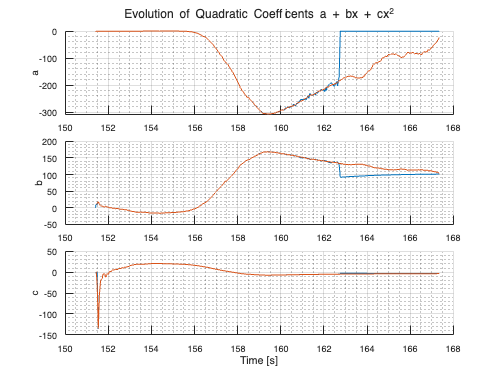



nexttile
hold on
plot(apo_detect.Time_s,apo_detect.coeffs(:,1))
plot(apo_detect.Time_s,apo_detect.computed_coeffs(:,1))
grid on
grid minor
ylabel('a')

nexttile
hold on
plot(apo_detect.Time_s,apo_detect.coeffs(:,2))
plot(apo_detect.Time_s,apo_detect.computed_coeffs(:,2))
grid on
grid minor
ylabel('b')

nexttile
hold on
plot(apo_detect.Time_s,apo_detect.coeffs(:,3))
plot(apo_detect.Time_s,apo_detect.computed_coeffs(:,3))
grid on
grid minor
ylabel('c')

title(t,'Evolution of Quadratic Coefficents a + bx + cx^2')
xlabel(t,'Time [s]')



figure

t = tiledlayout(2,1)

t =   TiledChartLayout with properties:

    TileArrangement: 'fixed'
           GridSize: [2 1]
            Padding: 'loose'
        TileSpacing: 'loose'

  Show all properties


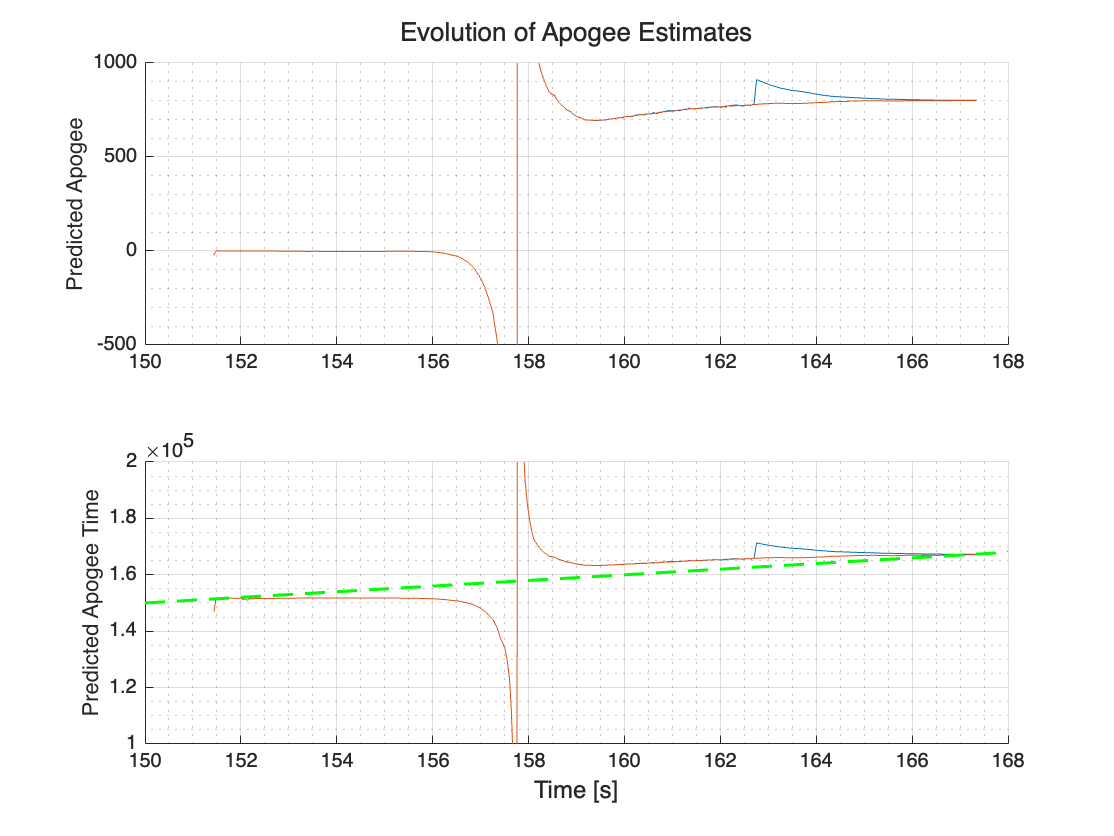


nexttile 
hold on
plot(apo_detect.Time_s,apo_detect.apogee)
plot(apo_detect.Time_s,apo_detect.computed_apogee)
grid on
grid minor
ylabel('Predicted Apogee')
ylim([-500 1000])

nexttile 
hold on
plot(apo_detect.Time_s,apo_detect.apogee_time)
plot(apo_detect.Time_s,apo_detect.computed_apogee_time)
fplot(@(x) x*1000,'--','color','green','linewidth',1.5)
grid on
grid minor
ylabel('Predicted Apogee Time')
xlim([150 168])
% ylim([apo_detect.initial_fit_time-1e5,apo_detect.initial_fit_time+1e5])
ylim([1e5,2e5])

title(t,'Evolution of Apogee Estimates')
xlabel(t,'Time [s]')

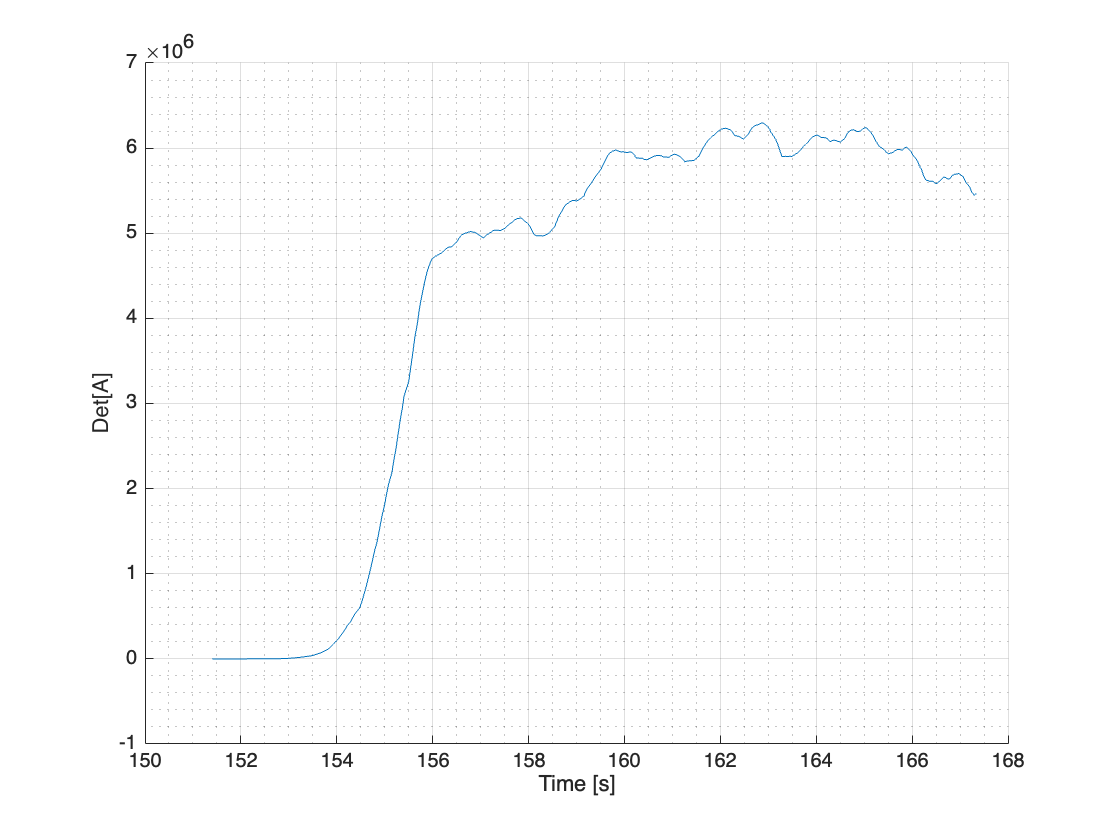


figure

hold on
plot(apo_detect.Time_s,apo_detect.a_det)
grid on
grid minor

ylabel('Det[A]')
xlabel('Time [s]')



figure
t =tiledlayout(4,2)

t =   TiledChartLayout with properties:

    TileArrangement: 'fixed'
           GridSize: [4 2]
            Padding: 'loose'
        TileSpacing: 'loose'

  Show all properties


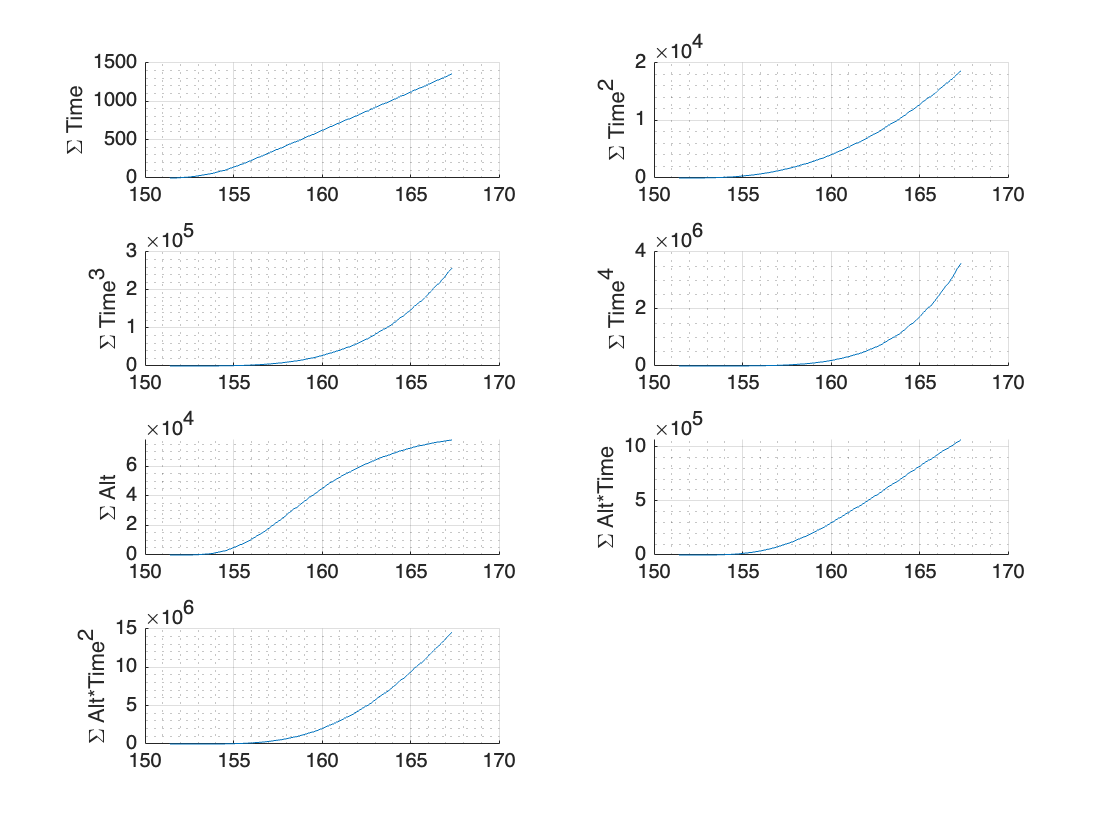


nexttile
hold on
plot(apo_detect.Time_s,apo_detect.sigmaTime)
grid on
grid minor
ylabel('\Sigma Time')

nexttile
hold on
plot(apo_detect.Time_s,apo_detect.sigmaTime2)
grid on
grid minor
ylabel('\Sigma Time^2')

nexttile
hold on
plot(apo_detect.Time_s,apo_detect.sigmaTime3)
grid on
grid minor
ylabel('\Sigma Time^3')

nexttile
hold on
plot(apo_detect.Time_s,apo_detect.sigmaTime4)
grid on
grid minor
ylabel('\Sigma Time^4')

nexttile
hold on
plot(apo_detect.Time_s,apo_detect.sigmaAlt)
grid on
grid minor
ylabel('\Sigma Alt')

nexttile
hold on
plot(apo_detect.Time_s,apo_detect.sigmaAltTime)
grid on
grid minor
ylabel('\Sigma Alt*Time')

nexttile
hold on
plot(apo_detect.Time_s,apo_detect.sigmaAltTime2)
grid on
grid minor
ylabel('\Sigma Alt*Time^2')

[https://gitlab.com/libeigen/eigen/-/issues/2318](https://gitlab.com/libeigen/eigen/-/issues/2318)